addpath('installation-module');

modelPath = fullfile(pwd, 'runs', 'detect', 'train6', 'weights');
configFile = 'data.yaml';

yolov8Det = utils.loadModel(modelPath, configFile);


**What is Non-Maximum Suppression (NMS) and Why is it Needed?**

In object detection models like **YOLO**, the network predicts **multiple bounding boxes** for each object in an image. This happens because:

- Each grid cell predicts multiple anchor boxes.

- Neighboring cells can detect the same object.

- As a result, **several overlapping boxes may represent the same object**.

If we keep all predicted boxes, the output would contain many duplicates.

**NMS is applied to reduce redundancy by selecting the best box per object.**

ScoreThreshold = 0.89

ScoreThreshold = 0.8900

Filtered: removed low-confidence detections
Filtered: removed low-confidence detections


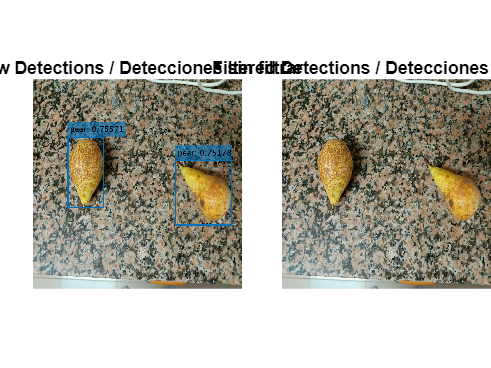

removeLowScore = @(results) arrayfun(@(r) filterStruct(r, ScoreThreshold), results);

filters = {removeLowScore};
filt = utils.Filter(yolov8Det, filters);
utils.displayFilteredDetections(yolov8Det, 'pear2.jpg', filt);


function rOut = filterStruct(r, threshold)
    % Removes detections below confidence threshold.
    conf = r.conf;
    keep = conf >= threshold;
    removed = sum(~keep);
    r.boxes = r.boxes(keep,:);
    r.conf  = r.conf(keep);
    r.cls   = r.cls(keep);
    if removed > 0
        fprintf('Filtered: removed low-confidence detections\n');
    end
    rOut = r;
end 

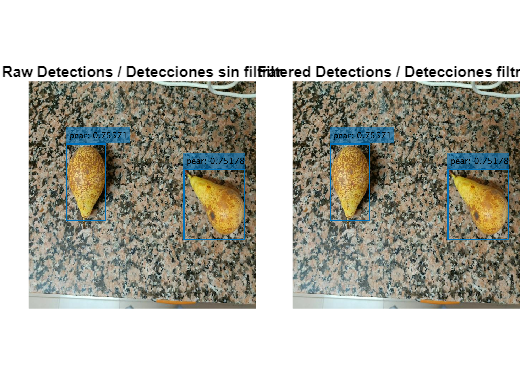

% Vector de umbrales por clase (índice = clase)
appleThreshold = 0.54;
bananaThreshold = 0.89;
pearThreshold = 0.66;

scoreThresholds = [appleThreshold, bananaThreshold, pearThreshold];

removeLowScorePerClass = @(results) arrayfun(@(r) filterStructPerClass(r, scoreThresholds), results);

filters = {removeLowScorePerClass};
filt = utils.Filter(yolov8Det, filters);
utils.displayFilteredDetections(yolov8Det, 'pear2.jpg', filt);


function rOut = filterStructPerClass(r, thresholds)
    %  Filter detections by threshold per class.
    cls = r.cls;
    conf = r.conf;
    keep = false(size(conf));
    for i = 1:numel(conf)
        classIdx = cls(i);
        if classIdx > 0 && classIdx <= numel(thresholds)
            keep(i) = conf(i) >= thresholds(classIdx);
        else
            keep(i) = false; 
        end
    end
    removed = sum(~keep);
    r.boxes = r.boxes(keep,:);
    r.conf  = r.conf(keep);
    r.cls   = r.cls(keep);
    if removed > 0
        fprintf('Filtered: removed %d low-confidence detections (per class)\n', removed);
    end
    rOut = r;
end 

function iou = calculateIoU(b1, b2)
        % CALCULATEIOU  Computes IoU between two bounding boxes.
        % b = [x1 y1 x2 y2]
        x1 = max(b1(1), b2(1));
        y1 = max(b1(2), b2(2));
        x2 = min(b1(3), b2(3));
        y2 = min(b1(4), b2(4));
        inter = max(0, x2-x1) * max(0, y2-y1);
        area1 = (b1(3)-b1(1))*(b1(4)-b1(2));
        area2 = (b2(3)-b2(1))*(b2(4)-b2(2));
        union = area1 + area2 - inter;
        if union>0
            iou = inter/union;
        else
            iou = 0;
        end
end

**How NMS Works**

The basic NMS algorithm consists of these steps:

- **Filter by Confidence Score: **Remove all boxes with confidence (objectness × class probability) below a threshold (e.g., `0.25`).

- **Sort Boxes by Score: **Arrange the remaining boxes in descending order of their confidence scores.

- **Suppress Overlapping Boxes**

- Take the box with the highest confidence, call it `B1`.

- Compute the **IoU (Intersection over Union)** of `B1` with all other boxes:IoU

- `Threshold` (e.g., `0.5`), discard those boxes since they likely represent the same object.

- Repeat with the next remaining box.

iouThreshold = 0.54;
function result = filterOverlapping(result, iouThreshold)
            % REMOVEOVERLAPPING  Removes same-class overlapping boxes.
            boxes = result.boxes;    % Nx4: [x1 y1 x2 y2]
            conf  = result.conf;     % Nx1
            cls   = result.cls;      % Nx1

            N = size(boxes,1);
            if N <= 1
                return
            end
            [~, order] = sort(conf, 'descend');
            keep = false(N,1);
            for k = 1:N
                idx = order(k);
                keepThis = true;
                for j = find(keep)'
                    if cls(idx)==cls(j)
                        iou = Filter.calculateIoU(boxes(idx,:), boxes(j,:));
                        if iou > iouThreshold
                            keepThis = false;
                            break
                        end
                    end
                end
                if keepThis
                    keep(idx) = true;
                end
            end
            removed = sum(~keep);
            result.boxes = result.boxes(keep,:);
            result.conf  = result.conf(keep);
            result.cls   = result.cls(keep);
            if removed>0
                fprintf('Filtered: removed %d overlapping detections\n', removed);
            end
end

removeOverlapping = @(results) arrayfun(@(r) filterOverlapping(r, iouThreshold), results);

filters = {removeOverlapping};
filt = utils.Filter(yolov8Det, filters);
utils.displayFilteredDetections(yolov8Det, 'pear2.jpg', filt);